[y,fs]=audioread('audio_files\guitarharmonic.wav')

y =    -0.0020
   -0.0010
    0.0005
    0.0008
   -0.0003
    0.0005
    0.0019
    0.0005
   -0.0005
   -0.0001


fs = 22050

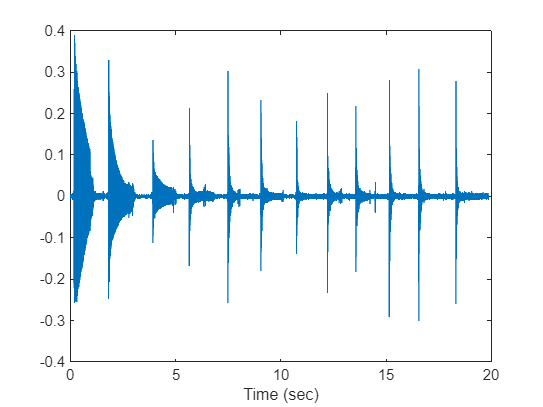

%sound(y,Fs);

N=numel(y); Dt=1/fs; tj=Dt*(1:N)'; T=N*Dt; Dnu=1/T;

figure(1); plot(tj,y); xlabel('Time (sec)');

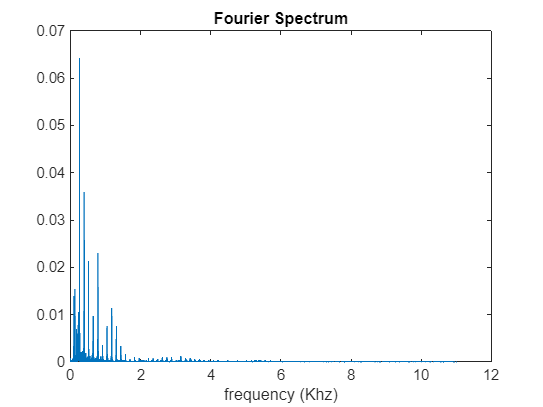


Y=fftshift(fft(y)); Y=[Y; Y(1)]*T/N;
nu=(-N/2:N/2)'/T;

m=N/2+1;

figure(2), plot(1e-3*nu(m:end),abs(Y(m:end))) %Khz
xlabel('frequency (Khz)'); title('Fourier Spectrum')

% Read the audio file
[y, fs] = audioread('audio_files\guitarharmonic.wav');

 % Parameters for STFT
 windowSize = fs*0.5;          % Size of the STFT window
 overlap = round(fs/12);   % Overlap between windows
 nfft = max(2048, 2^nextpow2(windowSize)); % Number of FFT points

 % Perform STFT
 [S, F, T] = stft(y, fs, 'Window', hamming(windowSize));
 m=ceil(numel(F)/2);
    
% Magnitude of the STFT
S_magnitude = abs(S).^2;

    % Frequency to Note mapping
    noteNames = {'C', 'C#', 'D', 'D#', 'E', 'F', 'F#', 'G', 'G#', 'A', 'A#', 'B'};
    baseFrequency = 440;  % Frequency of A4
    noteFrequencies = baseFrequency * 2.^(([0:87]-49)/12);  % Frequencies for the 88 keys on a piano

    % Detect notes in each time frame
    for t = 1:length(T)
        % Get the magnitude spectrum for the current time frame
        power = S_magnitude(:, t);
        
        % Find the frequency with the maximum magnitude
        [~, maxIdx] = max(power);
        dominantFreq = abs(F(maxIdx));
        
        % Find the closest note
        [~, noteIdx] = min(abs(noteFrequencies - dominantFreq));
        noteName = noteNames{mod(noteIdx - 1, 12) + 1};
        octave = floor((noteIdx - 1) / 12);
        
        % Display the detected note
        fprintf('Time %.2fs: Detected frequency: %.2f Hz corresponds to note: %s%d\n', T(t), dominantFreq, noteName, octave);
    end

Time 0.25s: Detected frequency: 262.00 Hz corresponds to note: E3
Time 0.38s: Detected frequency: 262.00 Hz corresponds to note: E3
Time 0.50s: Detected frequency: 262.00 Hz corresponds to note: E3
Time 0.63s: Detected frequency: 262.00 Hz corresponds to note: E3
Time 0.75s: Detected frequency: 262.00 Hz corresponds to note: E3
Time 0.88s: Detected frequency: 262.00 Hz corresponds to note: E3
Time 1.00s: Detected frequency: 262.00 Hz corresponds to note: E3
Time 1.13s: Detected frequency: 262.00 Hz corresponds to note: E3
Time 1.25s: Detected frequency: 262.00 Hz corresponds to note: E3
Time 1.38s: Detected frequency: 262.00 Hz corresponds to note: E3
Time 1.50s: Detected frequency: 262.00 Hz corresponds to note: E3
Time 1.63s: Detected frequency: 258.00 Hz corresponds to note: E3
Time 1.75s: Detected frequency: 262.00 Hz corresponds to note: E3
Time 1.88s: Detected frequency: 262.00 Hz corresponds to note: E3
Time 2.00s: Detected frequency: 262.00 Hz corresponds to note: E3
Time 2.13s